# **MATLAB Kursu**

*HAZIRLAYAN: BURAK ÖZPOYRAZ - burakozpoyraz@gmail.com / bozpoyraz20@ku.edu.tr*

## DERS - 4

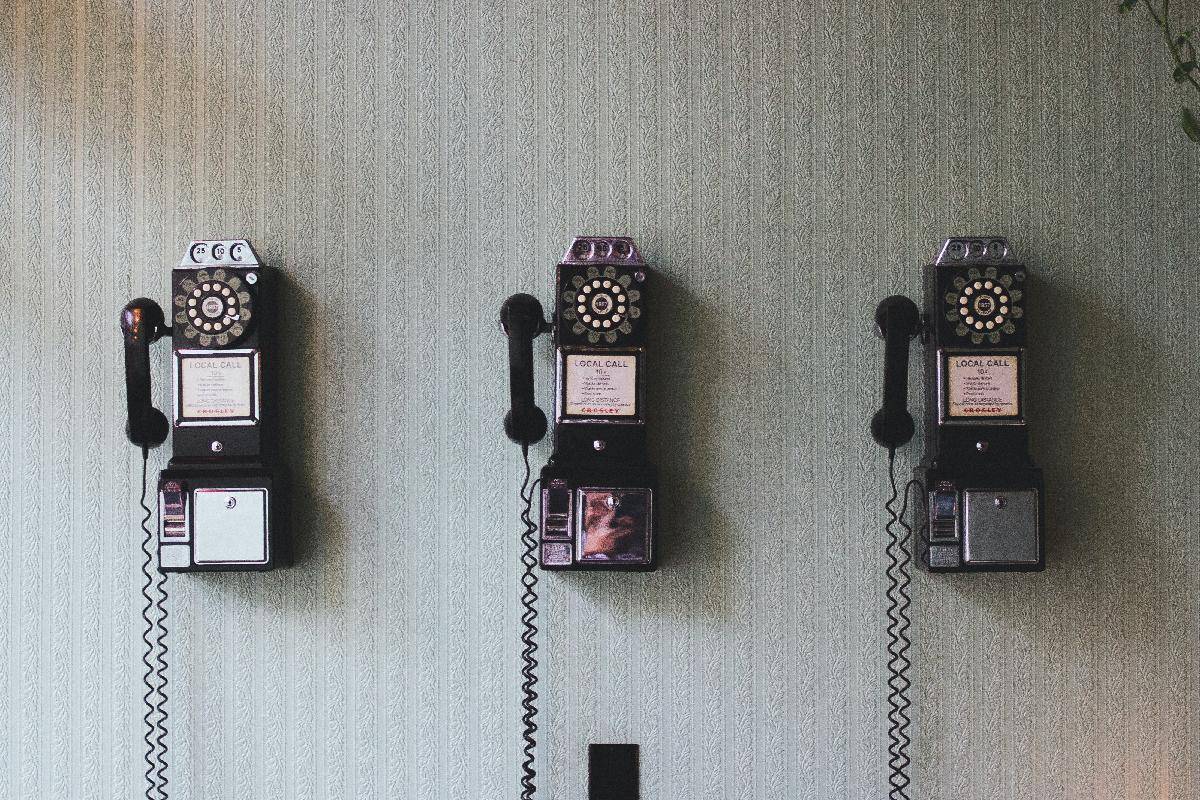

### 1) FONKSİYONLAR

Fonksiyonlar belirli girdilere göre belirli çıktılar veren yapılardır ancak her zaman girdi almak veya çıktı vermek zorunda değildirler. Fonksiyonlar, özellikle uzun programlarda karmaşıklığı azaltmak adına kullanılan çok işlevsel yapılardır.

- *"Aynı kodu iki defa yazıyorsanız burada bir problem vardır."*

Fonksiyonlar iki gruba ayrılırlar:

- Kullanıma hazır (built-in) fonksiyonlar

- Kullanıcı tarafından hazırlanan fonksiyonlar

#### 1.1) Kullanıma Hazır Fonksiyonlar (Built-In Functions)

MATLAB'de birçok farklı işlevi yerine getiren fonksiyonlar vardır. Bunlardan ilki **trigonometrik fonksiyonlar**dır. Bu fonksiyonlardan bir kısmını ilk derste öğrenmiştik:

- sin

- cos

- tan

- asin

- acos

- atan

Hazır fonksiyonların bir başka sınıfı da **üstel **ve **logaritmik** fonksiyonlardır. Bu fonksiyonlardan önemli olanları da yine ilk derste öğrenmiştik:

- sqrt

- log10

- log

Bunlara ek olarak aşağıdaki fonksiyonlar sık kullanılanlar arasındadır.

a = log2(8);
b = pow2(3);
c = nextpow2(33);

**Nümerik Türev**

Hazır fonksyionlardan ve temel kalkülüs bilgilerimizden faydalanarak nümerik olarak türev alma işlemi gerçekleştirebiliriz. Örneğin, elimizde $x_{1},x_{2},...,x_{N}$ değerlerinde hesaplanan $f(x_{i})$ fonksiyonları bulunsun. Burada $f$ fonksiyonunun türevini, $f'(x)$, aşağıdaki yakınsamayla bulabiliriz.


$$f'(x_{i}) \approx \frac{f(x_{i}) - f(x_{i-1})}{x_{i} - x_{i-1}}$$


Bu işlemi kolayca gerçekleştirebilmek için MATLAB'de hazır bulunan ***diff*** fonksiyonu kullanılabilir. Bu fonksiyon bir vektördeki birbirini takip eden elemanlar arasındaki farkları bularak yeni bir vektör elde eder.


$$diff(X) = [
\matrix{X(2)-X(1) & X(3)-X(2) & ... & X(n) - X(n-1)}
]$$


x = [2 5 -3 6];
diff_x = diff(x);

Bu durumda bir vektörün türevi aşağıdaki gibi elde edilebilir.

x = 0 : 0.01 : (2 * pi);
f = sin(x);
fd = diff(f) ./ diff(x);
xd = x(2 : end);
plot(x, f, "r", xd, fd, "b", xd, cos(xd), "g--", "LineWidth", 2);
legend("sin(x)","sin'(x)","cos(x)");
xlim([0 2 * pi]);
grid;

-----------------------------------------------------------------

**ÖRNEK - 1**

$f(x) = x^{2} + 4x + e^{x}$ fonksiyonunun türevini nümerik olarak elde ediniz ve $x=3$ değeri için olması gereken değeri alıp almadığını kontrol ediniz. Sonucu gerçek değere yaklaştıracak yöntemi bulunuz.

x = 0 : 0.00001 : 10;
f = x.^2 + 4 * x + exp(x);

fd = diff(f) ./ diff(x);
xd = x(2 : end);

ind3 = find(xd == 3);
fd3 = fd(ind3);

val = 3;
fd3_expected = 2 * val + 4 + exp(val);

-----------------------------------------------------------------

MATLAB'de tanımlı bir diğer fonksiyon sınıfı da **kompleks** **sayılar**la ilgilidir. Kompleks sayılarla kullanılabilecek önemli fonksiyonları ilk derste öğrenmiştik:

- conj

- real

- imag

**Tam sayılar **ile ilgili fonksiyonları da hatırlayacak olursak:

- floor

- ceil

- round

Bunlara ek olarak kullanılabilecek faydalı fonksiyonlar aşağıdaki gibidir.

d = fix(4.2);
e = sign(-5);

Bunlar haricinde sayıların işlenmesinde kullanılabilecek diğer fonksiyonlar aşağıdaki gibidir.

g = isprime(7);
h = gcd(25, 30);
i = lcm(6, 8);
comb = nchoosek(5, 3);
fac = factorial(5);

MATLAB'de **data analizi**nde kullanılabilecek çok işlevsel fonksiyonlar vardır.

vector = [1 3 -2 7];
max_val = max(vector);
min_val = min(vector);
m = mean(vector);
sigma = std(vector);
sigma2 = var(vector);
sorted_vector = sort(vector, "ascend");
sum_vector = sum(vector);
prod_vector = prod(vector);

-----------------------------------------------------------------

**ÖRNEK - 2**

Aşağıda verilen iki denklem eğer kesişiyorsa kesiştikleri noktayı bulunuz.


$$x^{2} + 2x - y = -1$$



$$y - 7 = x$$


x = -10 : 1 : 10;

y1 = x.^2 + 2 * x + 1;
y2 = x + 7;

sol_ind_array = find(y1 == y2);
sol_x_array = x(sol_ind_array);
sol_y_array = y1(sol_ind_array);

-----------------------------------------------------------------

#### 1.2) Kullanıcı Tarafından Hazırlanan Fonksiyonlar

Dersin başında bahsedildiği gibi kullanım kolaylığı açısından özel fonksiyonlar tanımlanabilir. Fonksiyonlar tanımlandıkları isimle aynı isimdeki dosyaya kaydedilmelidir. Yani mesela "myfunc" isminde bir fonksiyon oluşturulursa "myfunc.m" dosyası olarak kaydedilmelidir.

-----------------------------------------------------------------

**ÖRNEK - 3**

Aldığı girdinin faktöriyelini hesaplayıp çıktı olarak veren fonksiyonu yazarak sonrasında 1'den 10'a kadar tüm sayıların faktöriyelini hesaplayan kodu yazınız.

fact_array = zeros(1, 10);
fact_array_matlab = zeros(1, 10);
for i = 1 : 10
    fact_array(i) = MyFactorial(i);
    fact_array_matlab(i) = factorial(i);
end
equality = sum(fact_array == fact_array_matlab) ==...
    length(fact_array);

-----------------------------------------------------------------

**Rekürsif Fonksiyonlar**

İçerisinde kendini çağıran fonksiyonlara rekürsif fonksiyonlar denir.

-----------------------------------------------------------------

**ÖRNEK - 4**

Az önce oluşturduğumuz faktöriyel hesaplayan fonksiyonu rekürsif fonksiyon olarak yeniden oluşturunuz.

fact_array = zeros(1, 10);
fact_array_matlab = zeros(1, 10);
for i = 1: 10
    fact_array(i) = MyRecFactorial(i);
    fact_array_matlab(i) = factorial(i);
end
equality = sum(fact_array == fact_array_matlab)...
    == length(fact_array);

-----------------------------------------------------------------

### 2) PROBLEMLER

#### Problem - 1 / Banknot Sayar

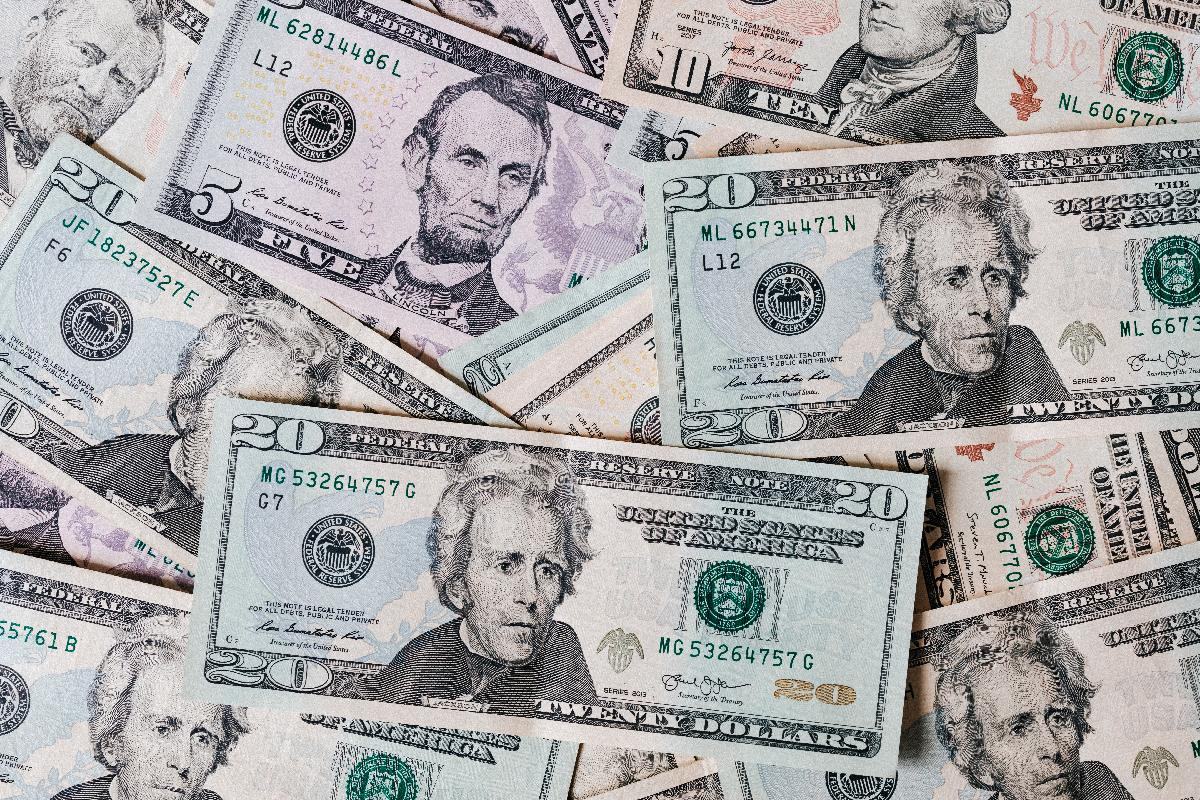

Girdi olarak bir para değeri alıp, parayı en az banknotla elde edecek şekilde her banknottan kaçar tane olduğunu matris olarak çıktıya veren fonksiyonu oluşturunuz. Örnek olarak para değeri 359 ise çıktıda elde edilmesi beklenen matris aşağıda verildiği gibidir:


$$\matrix{
200 & 100 & 50 & 5 & 1 \cr
1 & 1 & 1 & 1 & 4
}$$


Fonksiyon sonucunda elde edilen matrisin doğru sonuç verip vermediğini, matristeki paraları toplayarak beklenen para değerine eşit olup olmadığına bakarak kontrol ediniz.

m = 359;
M = Money(m);
equality = sum(M(1, :) .* M(2, :)) == m;

#### Problem - 2 / Kaç Basamaklı?

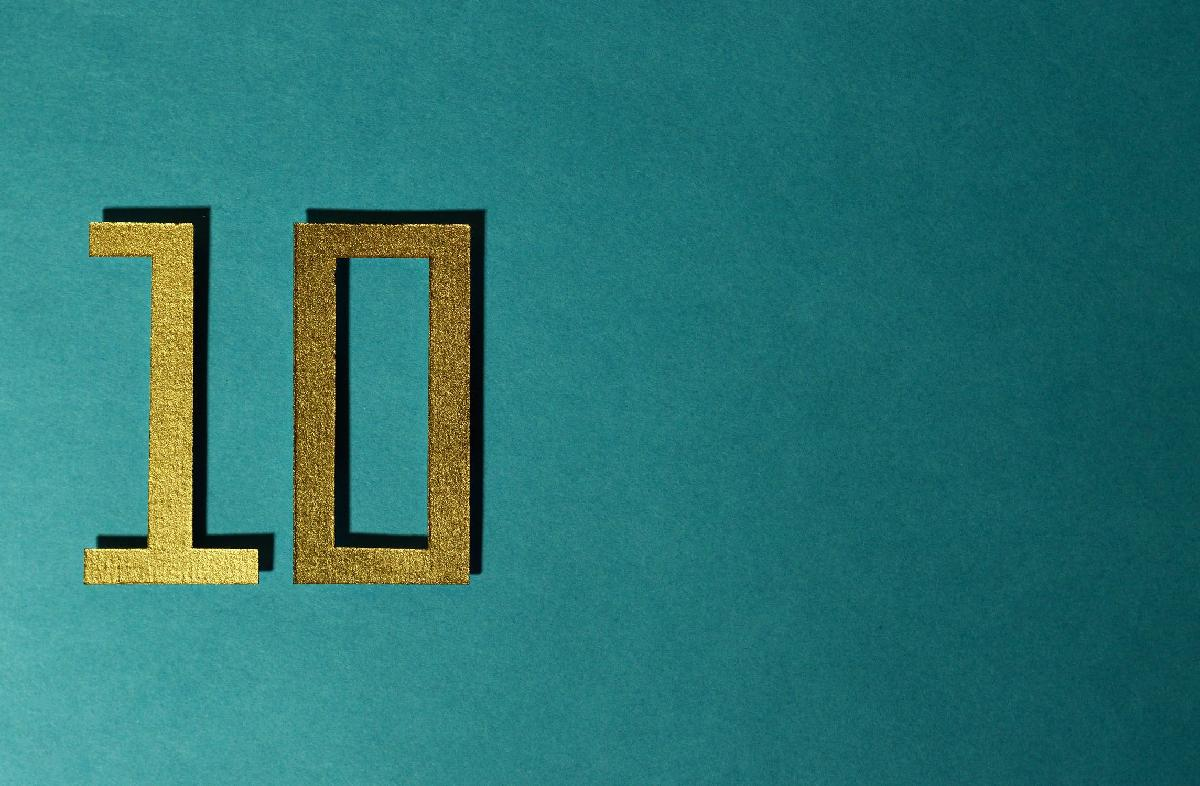

Girdi olarak bir pozitif tam sayı alıp, sayının kaç basamaklı olduğunu tespit ettikten sonra basamak sayısı ve tüm basamaklardan oluşan matrisi çıktıya veren fonksiyonu oluşturunuz. Örnek olarak girdi 2563 ise çıktıda elde edilmesi beklenen matris aşağıda verildiği gibidir:


$$\matrix{
\text{0} & \text{1000} & \text{100} & \text{10} & \text{1} \cr
4 & 2 & 5 & 6 & 3
}$$


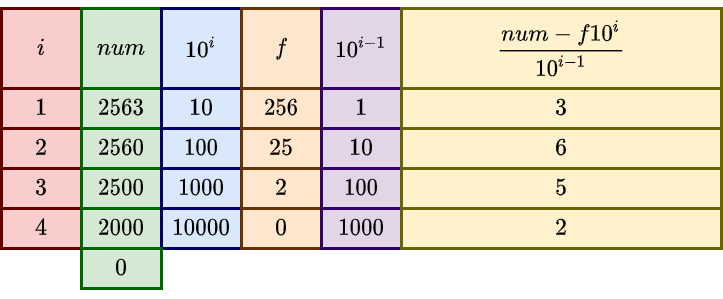

Çıktıda elde ettiğiniz matrisin doğruluğunu kontrol etmek için matristeki basamaklardan oluşan sayının beklenen sayıya eşit olup olmadığını kontrol ediniz.

num = 2563;
M = Digit(num);
equality = sum(M(1, 2 : end) .* M(2, 2 : end)) == num